# DSP

## Hamidreza-AliAkbaryKhoyi

810196514

## Question1

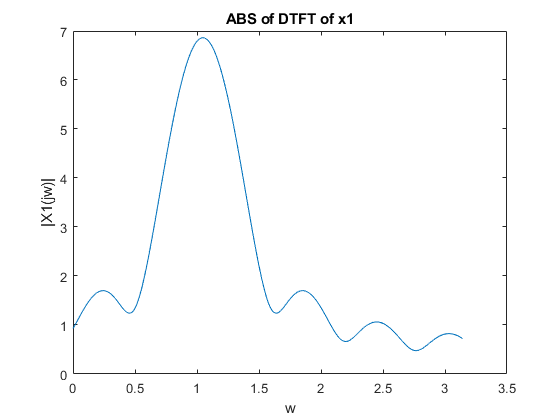

rangex1=0:10;
rangex2=-10:10;
M=1000;
x1 = (0.9*exp(1i*pi/3)).^rangex1;
DTFTX1 = DTFT(x1,rangex1,M);
x2 = (0.9).^rangex2;
DTFTX2 = DTFT(x2,rangex2,M);
w=linspace(0,pi,M+1);
figure
plot(w,abs(DTFTX1))
title('ABS of DTFT of x1')
xlabel('w')
ylabel('|X1(jw)|')

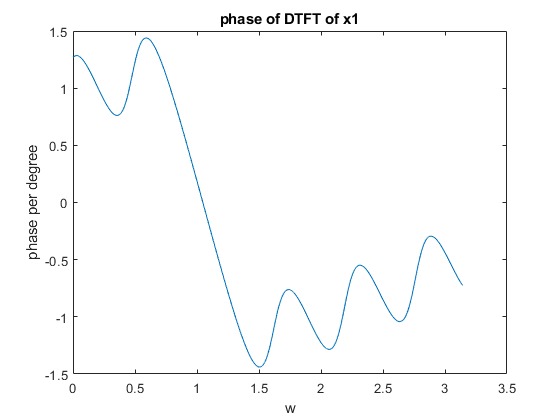

figure
plot(w,phase(DTFTX1))
title('phase of DTFT of x1')
xlabel('w')
ylabel('phase per degree')

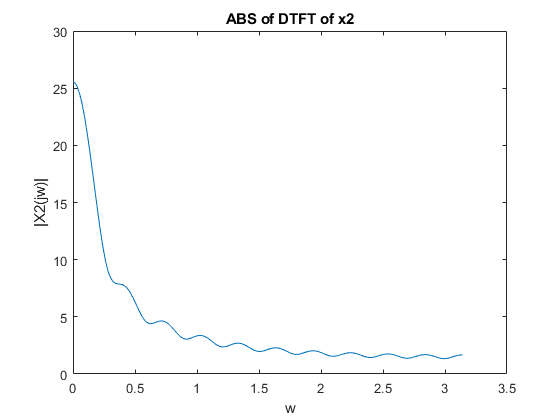

figure
plot(w,abs(DTFTX2))
title('ABS of DTFT of x2')
xlabel('w')
ylabel('|X2(jw)|')

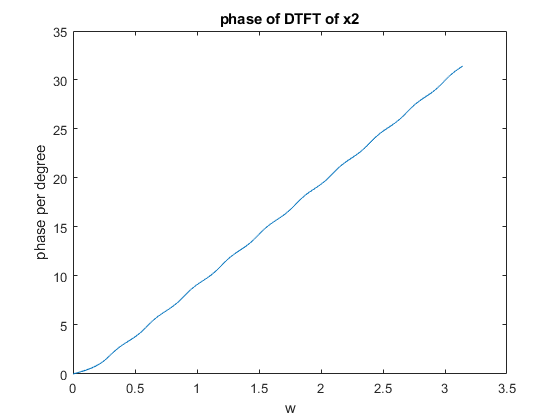

figure
plot(w,phase(DTFTX2))
title('phase of DTFT of x2')
xlabel('w')
ylabel('phase per degree')

as it is obvious to see by defining the DTFT function to use it through question 1 we oughta know in discrete frequency domain we have signals with 2pi rad in periodic .

## Question2

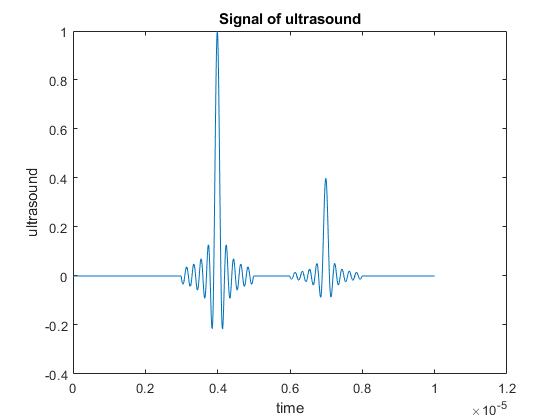

Signal=ultrasound.signal;
Time=ultrasound.time;
Fs=ultrasound.fsample;
figure
plot(Time,Signal)
title('Signal of ultrasound')
xlabel('time')
ylabel('ultrasound')

[~,Peaks] = findpeaks(ultrasound.signal, ultrasound.time, ...
    'MinPeakHeight', 0.2*max(Signal));
blood_vessel_Diameter=abs(peaks(1) - peaks(2))*1540./(2);

As it is simple to see from signal of ultrasound we have two peaks that it can be detected by findpeaks func but we should set a threshhold to it and because of that i used 1 of 5 of signal to give a little flexibility to it.

blood vessel answer was 2.3mm.

Next, i tried to show blood vessel diameter to SNR rate form 0 to 100 (not in db) as showed in figure we are able to detect signal it self with snr rate of about 50.

dynamic_snr=linspace(100,3,1000);
signal_and_noise=zeros(1,length(dynamic_snr));
noise_peaks=zeros(1000,2);
BVLdiameter=zeros(1,1000);
for i=1:1000
signal_and_noise=awgn(Signal,dynamic_snr(i));
[~,temp0] = findpeaks(signal_and_noise,Time, ...
    'MinPeakHeight',0.2*max(signal_and_noise));
noise_peaks(i,1)=temp0(1);
noise_peaks(i,2)=temp0(2);
BVLdiameter(i)=abs(noise_peaks(i,1)-noise_peaks(i,2))*1540./(2);
end

to enhance signal with nises that has an snr that signl soesn't change it's topology in that snr we could use an algorith called moved average to do that option and we could reach to real blood vessel diameter as using functons like smoothdata that it will enhance all data to catch peaks to calculate blood vessel diameter and again it becomes 2.3 mm.

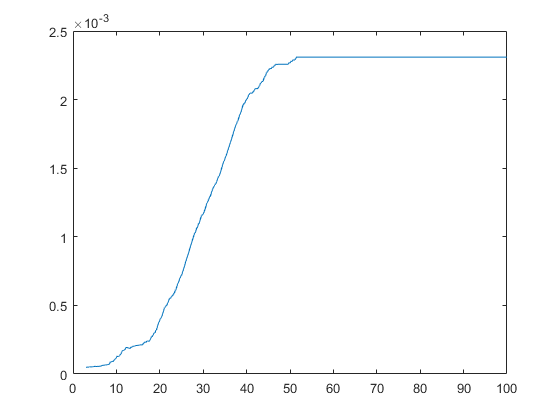

enhanced=smoothdata(BVLdiameter);
plot(dynamic_snr,enhanced);

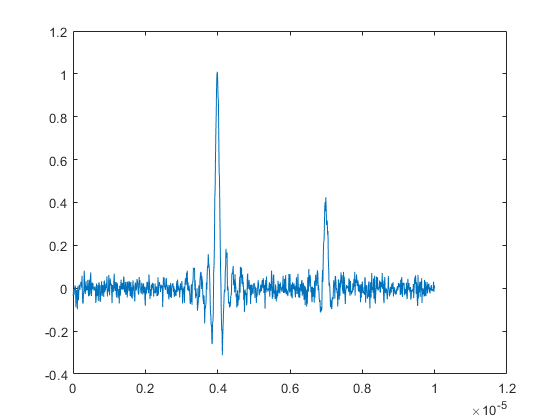

noisy=awgn(Signal,30);
plot(Time,awgn(Signal,30));

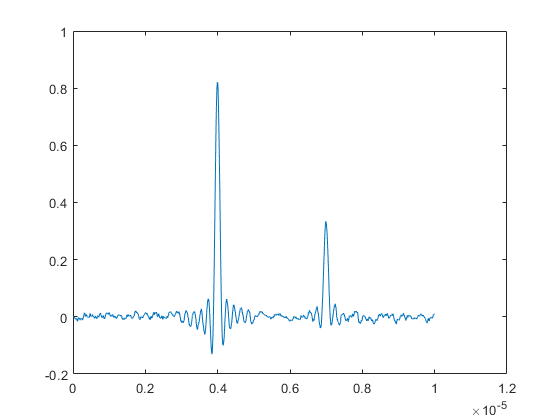

enhanced_noisy=smoothdata(noisy);
[~,localpeak]=findpeaks(enhanced_noisy,Time,'MinPeakHeight',0.2*max(enhanced_noisy));
enhanced_blood_vessel_diameter=abs(localpeak(1)-localpeak(2))*1540./2;
%moved=step(enhanced);
plot(Time,enhanced_noisy);

## Question3

First of all it was nice music realy :) please note the performer in next time please.

AS we are to get FFT of music which is given.after that we should do 2 different thing on that FFT.First, we should downsample with factor of 2 and then decimate it.Second,we should upsaple signal with factor of 2 and then Interpolate it.Both decimation and interpolation is because of preventing aliasing.Because in this particular example our sampling rate was overnyquist so with these 2 effect we didn't have any frequency interferance(as plots ahow that too).

in playing sounds, in upsampling we are doubling sampling rate and though the quality of resulted signal is better than othar one which was interpolated, because we put enhanced samples instead of zeros.in downsapling we are dividing frequency of sampling into 2 same part,and here quality of both decimation and downsampling is same because we dont have any kind of frequency domain interferance.

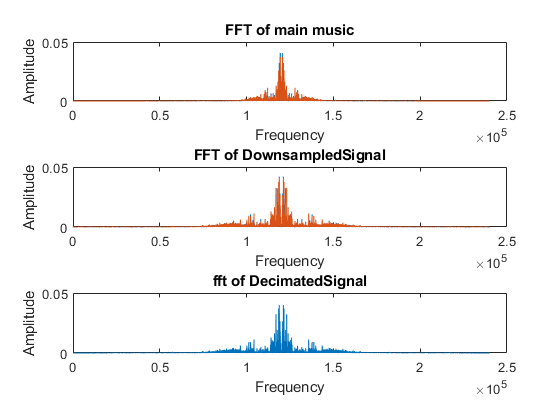

%[data,fs]=audioread("music.mp3");
Signal=data(floor(end/2):floor(end/2 + 5*fs),:);
sound(data,fs);
Nom_points = length(Signal);
FFT_Signal = Fourier_Transform(Signal,Nom_points);
DownSmpld_Signal = downsample(Signal,2);
Decimate_Signal = decimate(Signal,2);
FFT_Down_Signal = Fourier_Transform(DownSmpld_Signal,Nom_points);
FFT_Dec_Signal = Fourier_Transform(Decimate_Signal,Nom_points);
UPSmpld_Signal = upsample(Signal,2);
Interp_Signal = interp(Signal(:,2),2);
FFT_UPSmpld_signal = Fourier_Transform(UPSmpld_Signal,Nom_points);
FFT_Interp_Signal = Fourier_Transform(Interp_Signal,Nom_points);
figure
subplot 311
plot(FFT_Signal)
title('FFT of main music')
xlabel('Frequency')
ylabel('Amplitude')
subplot 312
plot(FFT_Down_Signal)
title('FFT of DownsampledSignal')
xlabel('Frequency')
ylabel('Amplitude')
subplot 313
plot(FFT_Dec_Signal)
title('fft of DecimatedSignal')
xlabel('Frequency')
ylabel('Amplitude')

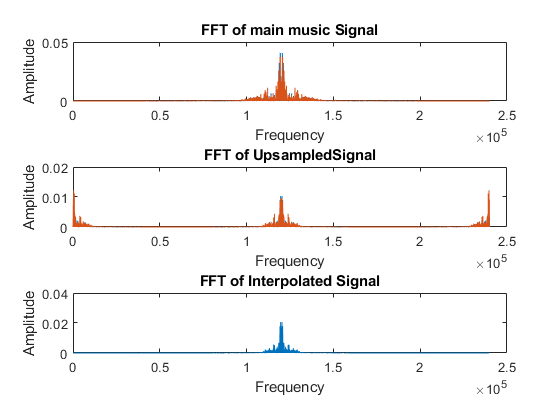


figure
subplot 311
plot(FFT_Signal)
title('FFT of main music Signal')
xlabel('Frequency')
ylabel('Amplitude')
subplot 312
plot(FFT_UPSmpld_signal)
title('FFT of UpsampledSignal')
xlabel('Frequency')
ylabel('Amplitude')
subplot 313
plot(FFT_Interp_Signal)
title('FFT of Interpolated Signal')
xlabel('Frequency')
ylabel('Amplitude')

## Question4

it is obvious that stability of a system is related to its poles in dicrete time filters stavility refers to farthest zero that if it was in unit circle.

as we can solve the poles of system based on r and \omega .the image was uploaded with zip file.

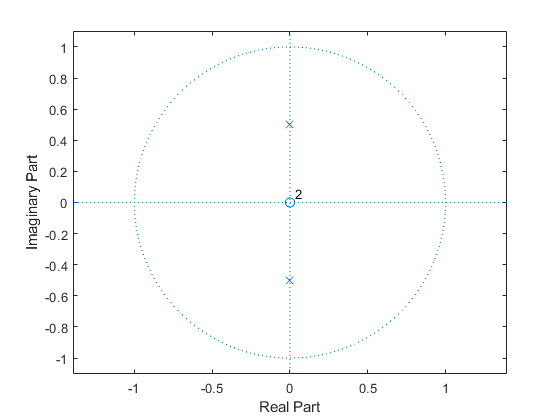

figure
zplane(1,[1 0 0.25]);

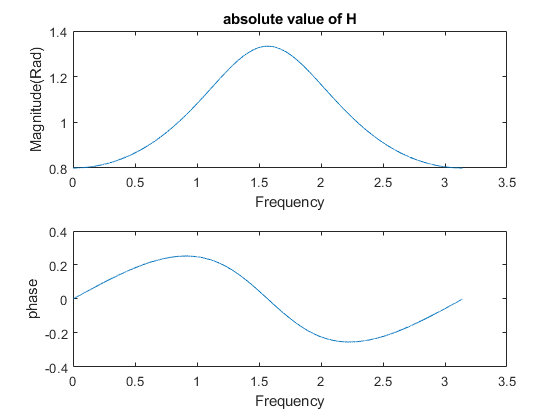

[H,W]=freqz(1,[1 0 0.25],10000);
figure
subplot 211
plot(W,abs(H));
title('absolute value of H')
xlabel('Frequency')
ylabel('Magnitude(Rad)')
subplot 212
title('Frequency of H')
plot(W,phase(H));
xlabel('Frequency')
ylabel('phase')

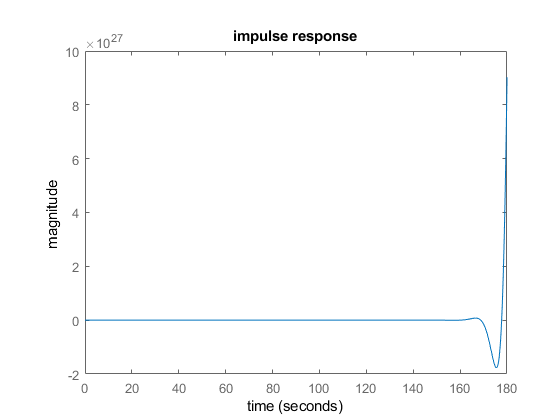

figure
[U,W]=freqz(0,1,10000);
%plot(iztrans(H));
b = [1];
a = [1, -2*(0.5)*cos(pi/4), (0.5)^2];
sys = tf(b, a);
figure, impulse(sys);
title('impulse response');
xlabel('time')
ylabel('magnitude')